%康托尔点集（for循环例子）

u=[0+3i,1+3i]; plot(u) %复平面画图
axis([0 1 0 3.1]), hold on
for k=2:6
    u=[u/3,NaN,u/3+2/3]+2i/k;
    plot(u);
end

矢量化编程代替for循环

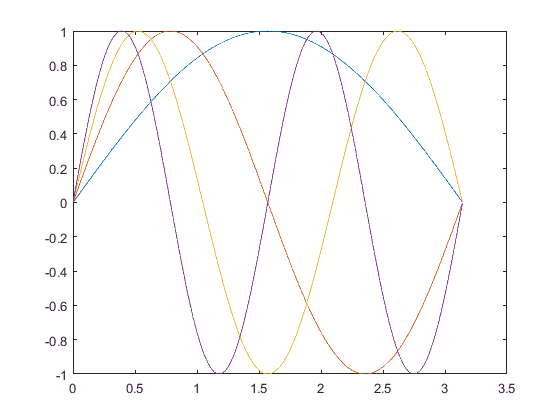

x=0:0.001*pi:pi; %变量x
y=sin([1:4].'*x); %函数值y是一个矩阵
plot(x,y); %用y的每行对x画图

while循环结构

例子：求小于$10^{10}$的阶乘

n=1;
while prod(1:n)<1e10 %prod计算阶乘
    n
    n=n+1;
end

if结构例子，建立sinc函数

x=input('输入x=') %input为请求用户输入
if x==0
    y=1;
else
    y=sin(x)/x
end

switch例子，学生成绩分段

W={'赵','李','陈','张';86,78,65,50}; %基元数组
for k=1:4
    switch W{2,k}
        case num2cell(86:100), r='A'; %将向量改为基元数组才可比较
        case num2cell(70:85),  r='B';
        case num2cell(60:69),  r='C';
        otherwise, r='D';
    end
    W(3,k)={r};
end
W

W =     '赵'    '李'    '陈'    '张'
    [86]    [78]    [65]    [50]
    'A'     'B'     'C'     'D' 


try结构

A=[1,3,5,7,9;2,4,6,8,10];
B=[1,3,5,7,9;2,4,6,8,10];
try
    A*B
catch
    A.*B
end

ans =      1     9    25    49    81
     4    16    36    64   100
